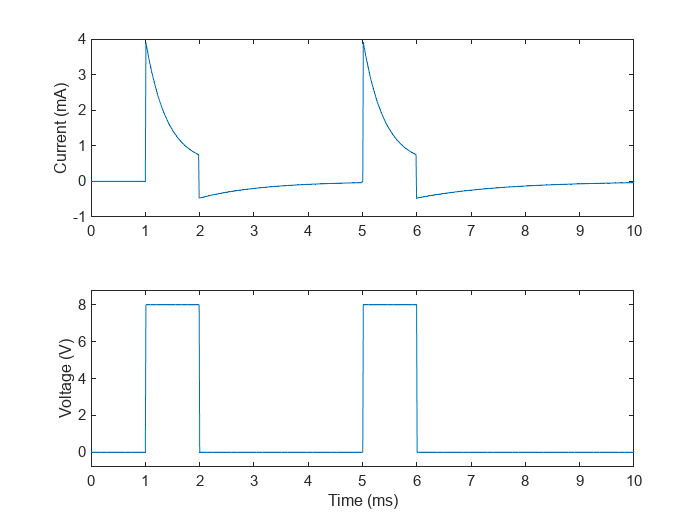

%{
---------------------
Code for V_over_time:
---------------------
function out = V_over_time(t,V_prot,pStart,pEnd)
    out = zeros(1);
    for i = 1:length(t)
        if t(i) > pStart && t(i) < pEnd
            out(i) = V_prot;
        else
            out(i) = 0;
        end
    end
end

--------------------
Code for I_biphasic:
--------------------
function out = I_biphasic(V,Rs,Rct,tPulse,Rpar,Cdl)
    % Current with voltage stimulation
    out = (V/(Rs+Rct)).*(1+(Rct/Rs)*exp(-tPulse/(Rpar*Cdl)));
   
    % Current following voltage stimulation
    tau = Rpar*Cdl;

    t1 = linspace(0,1e-3,300);
    out(200:499) = -exp(-t1/tau)*(max(V)/(Rs+Rct));

    t2 = linspace(0,1e-3,400);
    out(600:999) = -exp(-t2/tau)*(max(V)/(Rs+Rct));
end

%}

close all
% 1.1(a)

% All terms should be converted to the following units:
% - Ohms, Farads, s, V

Rs = 2000; % Ohms
Rct = 15000; % Ohms
Cdl = 220e-9; % Farads
Rpar = (Rs*Rct)/(Rs+Rct);

% Only works for even values of numPulse
tStart = 0;
tEnd = 10e-3;
numPulse = 2;
numSteps = 1000;

t = linspace(tStart,tEnd,numSteps);
tPulse = [linspace(0,0,100) linspace(0,4e-3,400) linspace(0,4e-3,400) linspace(0,0,100)];

pw = 1e-3; % s
pStart = 0; % Start pulse at t=1ms and t=5ms
pEnd = pStart+pw; % End pulse 'pw' ms after pStart

V_prot = 8; % V
V = V_over_time(tPulse,V_prot,pStart,pEnd);

% I = (V/(Rs+Rct)).*(1+(Rct/Rs)*exp(-tPulse/(Rpar*Cdl)));
I = I_biphasic(V,Rs,Rct,tPulse,Rpar,Cdl);

ax1 = nexttile;
plot(t*1000,I*1000)
ylabel("Current (mA)"); %ylim([-0.4 4.4])

ax2 = nexttile;
plot(t*1000,V);
ylabel("Voltage (V)"); ylim([-0.8 8.8])
xlabel("Time (ms)");
linkaxes([ax1,ax2],'x')

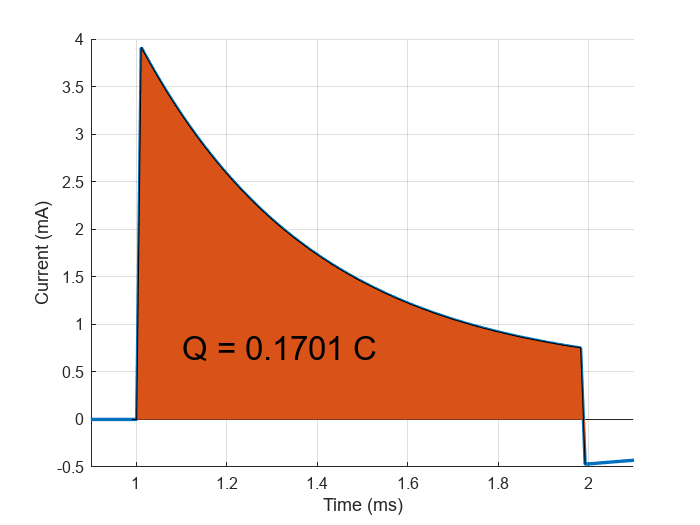

close all
% 1.1(b)
Q = trapz(I(100:200));

hold on
plot(t*1000,I*1000,LineWidth=2);
area(t(100:200)*1000,I(100:200)*1000)
text(1.1,0.75,"Q = "+num2str(Q,4)+" C",fontsize=20)
xlabel("Time (ms)"); xlim([0.9,2.1])
ylabel("Current (mA)");
grid on
hold off

% The charge of the current stimulation in the new protocol is 0.1701 C

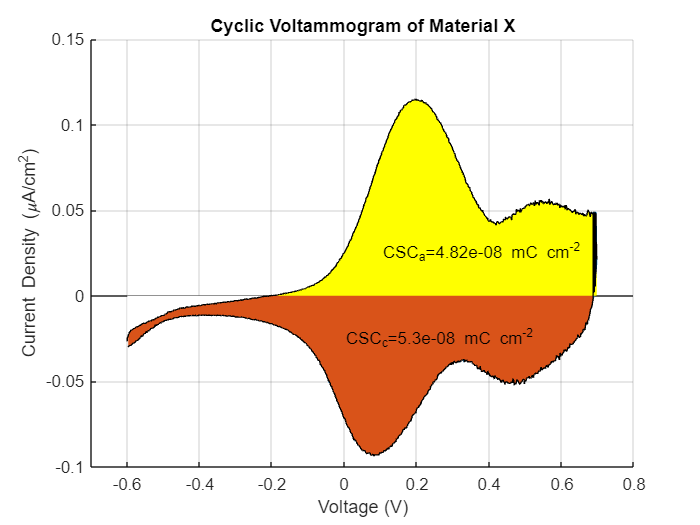

close all
% 1.2 preprocessing
cv_data = readmatrix("homework-3-2022-fall-cv.xls");
I = cv_data(:,2);
V = cv_data(:,1);

left_I0 = 197;  % The index of the leftmost I-intercept
right_I0 = 657; % The index of the rightmost I-intercept

hold on
plot(V,I*1e6)
area(V(right_I0:end,:),I(right_I0:end,:)*1e6)
area(V(1:left_I0,:),I(1:left_I0,:)*1e6,FaceColor="w");

CSC_c = trapz(V(right_I0:end,:),I(right_I0:end,:))-trapz(V(1:left_I0,:),I(1:left_I0,:));
text(0,-0.025,"CSC_c="+num2str(CSC_c,3)+" mC cm^{-2}")

area(V(left_I0:right_I0,:),I(left_I0:right_I0,:)*1e6,FaceColor='y')

CSC_a = trapz(V(left_I0:right_I0,:),I(left_I0:right_I0,:));
text(0.1,0.025,"CSC_a="+num2str(CSC_a,3)+" mC cm^{-2}")

ylabel("Current Density (\muA/cm^2)");
xlabel("Voltage (V)"); xlim([-0.7 0.8])
title("Cyclic Voltammogram of Material X");
grid on

hold off

Q_cathode = (CSC_c) / (210e-3)

Q_cathode = 2.5233e-07

Q_anode = (CSC_a) / (210e-3)

Q_anode = 2.2955e-07

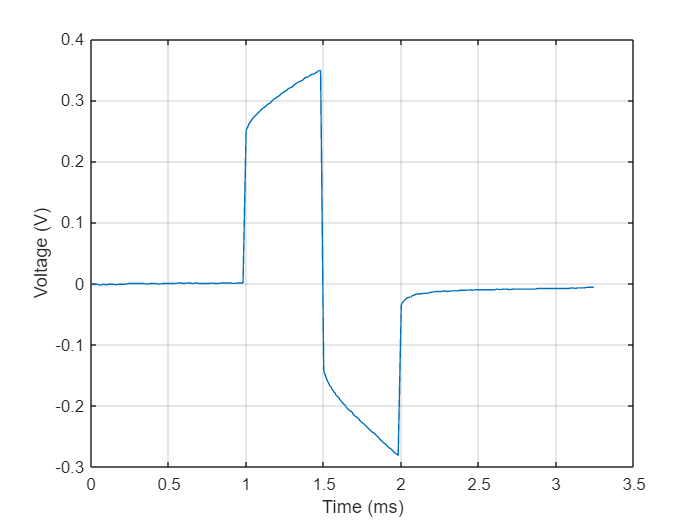

close all
pw_data = readmatrix("homework-3-2022-fall-pw.xls");

time = pw_data(:,1);
pulse = pw_data(:,2);
plot(time, pulse);
xlabel("Time (ms)");
ylabel("Voltage (V)");
grid on

max(pulse)

ans = 0.3490

min(pulse)

ans = -0.2810

% 1.2(a)

% At t = 1ms when the first pulse begins, we see a virtually instantaneous 
% voltage increase from 0V to 0.251V. This portion of the voltage waveform
% corresponds to the Ohmic Voltage (V = I*Rs) and can therefore be used
% to estimate Rs:
delV = 0.251; % V
I = 50e-6;   % A
Rs = delV/I

Rs = 5020

% == From the equation Q = CV
V_ww = 1.5; % V (The water window)
Q_csc = min(Q_anode,Q_cathode);
Cdl = Q_csc/V_ww

Cdl = 1.5303e-07

% Using V(0.5ms)=0.35V from the provided data, we can usethe equation 
% V(t) = IR_s + IR_ct*(1-e^(-t/(Rct*Cdl))) to compute Rct because it is the
% only remaining unknown. The solution to the equation is:
Rct=2964.37

Rct = 2.9644e+03

% My estimations are: Rs = 5.02 kOhms, Cdl = 15.3 uF, and Rct = 2.96 kOhm

% 1.2(b)
Q_csc = min(Q_anode,Q_cathode)

Q_csc = 2.2955e-07

I_prot = 0.5e-6; % Amps
pw = 0.5e-3;     % s
Qinj = I_prot*pw

Qinj = 2.5000e-10

prop = (Qinj/Q_cathode)*100

prop = 0.0991

% 0.0991% of the charge storage capacity can be used 

% 1.2(c)

% To compute solution resistance, we can use the equation Rs=rho/4a.
% Solving this equation for a can provide us with the electrode radius at
% different temperatures.

Rs = 5020; % Ohms
res_37 = 0.502; % Ohms-m
res_20 = 0.7; % Ohms-m

a_37 = res_37/(4*Rs)

a_37 = 2.5000e-05

a_20 = res_20/(4*Rs)

a_20 = 3.4861e-05

% At 37 degrees C, the electrode diameter is 50 um
% At 20 degrees C, the electrode diameter is 69.6 um

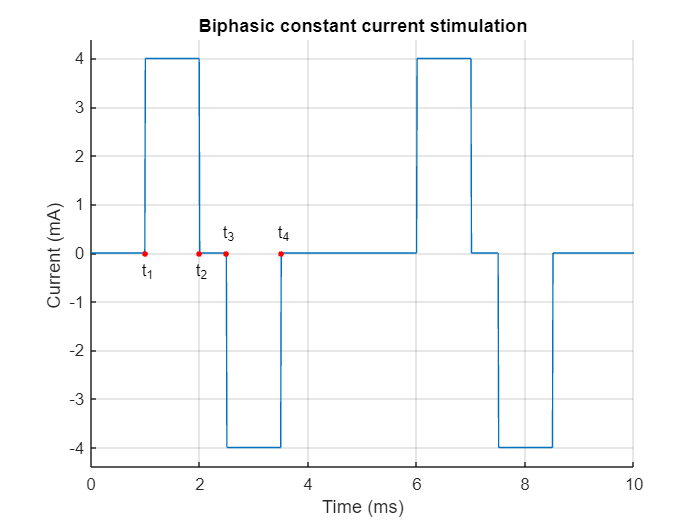

close all
% 1.3 Introduction

% A biphasic constant current stimulation for a non-faradaic electrode with
% the anodic electrode being first would have the following waveform:
[t,I] = I_1_3_waveform();

hold on
plot(t,I)
title("Biphasic constant current stimulation")
xlabel("Time (ms)");
ylabel("Current (mA) "); ylim([min(I)*1.1 max(I)*1.1]);
text(0.9,-0.4,"t_1"); plot(1,0,'r.',MarkerSize=10)
text(1.9,-0.4,"t_2"); plot(2,0,'r.',MarkerSize=10)
text(2.4,0.4,"t_3"); plot(2.5,0,'r.',MarkerSize=10)
text(3.4,0.4,"t_4"); plot(3.5,0,'r.',MarkerSize=10)
grid on
hold off

% 1.3(a)

% For a non-faradaic electrode (i.e. Rct = infinity), 
% V(t) = IR_s + (I/C)(t-t_0) for a step function starting at t_0

% Therefore, for a biphasic pulse at t = T:
% V(T) = (IR_s + (I/C)(T-t_1)) - (IR_s + (I/C)(T-t_1)) - (IR_s +
% (I/C)(T-t_1)) + (IR_s + (I/C)(T-t_1))

% The IR_s and T terms all cancel out, resulting in:
% V(T) = (I/C)(-t_1 + t_2 + t_3 - t_4)

% Since the stimulation pulse is balanced (i.e. t_2-t_1 = t_4-t_3) and the
% charge in the anodic and cathodic phases must be equal:
% V(T) = (I/C)(0)
% V(T) = 0

% Therefore, no residual charge exists for a non-Faradaic electrode

% 1.3(b)

% For a Faradaic electrode (i.e. Rcy is finite),
% V(t) = [IR_s + IR_ct*(1-exp(-(t-t_0)/tau))]*u(t-t_0) for a step function
% starting at t_0

% Therefore, for a biphasic pulse at t = T:
% V(T) = [IR_s + IR_ct*(1-exp(-(T-t_1)/tau))]*u(T-t_1) 
%      - [IR_s + IR_ct*(1-exp(-(T-t_2)/tau))]*u(T-t_2)
%      - [IR_s + IR_ct*(1-exp(-(T-t_3)/tau))]*u(T-t_3)
%      + [IR_s + IR_ct*(1-exp(-(T-t_4)/tau))]*u(T-t_4)

% The IR_s and IR_ct terms cancel out, and if we set t_1 = 0, this results
% in the following:
% V(T) = IR_ct*[exp(-(T/tau)) + exp(-((T-t_2)/tau)) + exp(-((T-t_3)/tau)) - exp(-((T-t_4)/tau))]

% Therefore, a residual charge exists for Faradaic electrodes

% 1.3(c)

% Since the residual charge is an exponential decay function, we can wait
% for some extended period of time for V(t) to approach 0. This works
% because for exponentially decaying functions, as t approaches infinity,
% the value of the function approaches 0.

% 1.3(d)

% For a Faradaic electrode, with an infinite pulse train of biphasic
% constant current stimulation,


$$V(kT) = \sum^{\infty}_{k=1} IR_{ct}[ -e^{-kT/\tau} +e^{-(kT-t_2)/\tau} +e^{-(kT-t_3)/\tau} -e^{-(kT-t_4)/\tau}]$$



$$V(kT) = IR_{ct}[ -\sum^{\infty}_{k=1}e^{-kT/\tau} +\sum^{\infty}_{k=1}e^{-(kT-t_2)/\tau} +\sum^{\infty}_{k=1}e^{-(kT-t_3)/\tau} -\sum^{\infty}_{k=1}e^{-(kT-t_4)/\tau}]$$



$$V(kT) = IR_{ct} [- \frac{e^{-T/\tau}}{1-e^{-T/\tau}} + \frac{e^{-(T-t_2)/\tau}}{1-e^{-(T-t_2)/\tau}} + \frac{e^{-(T-t_3)/\tau}}{1-e^{-(T-t_3)/\tau}} - \frac{e^{-(T-t_4)/\tau}}{1-e^{-(T-t_4)/\tau}}]$$


% Yes, the accumulated residual charge will reach a steady state in this
% scenario and only depends on the previous biphasic pulse.

% 1.4(a)
% == The voltage drop corresponding to the faradaic reaction
% V = I*Rct*(1-exp(-t/(Rct*Cdl)));

I = 0.2e-3; % Amps
Rct = 15e3; % Ohms
Rs = 2e3; % Ohms
Cdl = 220e-9; % Farad
pw = 1e-3; % s

V = I*Rct*(1-exp(-pw/(Rct*Cdl)))

V = 0.7843

% The voltage drop resulting from a constant current pulse
% stimulation of 0.2 mA with a pulse width of 1 ms is 0.7843 V. 
% Since the water window for this electrode was determined to 
% be [-0.8V 0.8V] and -0.8V < 0.7843V < 0.8V, this is current pulse is
% safe.

% 1.4(b)
% == The voltage drop corresponding to the faradaic reaction
% V = I*Rct*(1-exp(-t/(Rct*Cdl)));

I = 2e-3; % Amps
Rct = 15e3; % Ohms
Rs = 2e3; % Ohms
Cdl = 220e-9; % Farad
pw = 1e-3; % s

V = I*Rct*(1-exp(-pw/(Rct*Cdl)))

V = 7.8427

% The voltage drop resulting from a constant current pulse
% stimulation of 2 mA with a pulse width of 1 ms is 7.8427 V. 
% Since the water window for this electrode was determined to 
% be [-0.8V 0.8V] and 0.8V < 7.8427 V, this is current pulse is
% NOT safe.